% Scaricare dal sito di Yahoo le quotazioni di poste italiane alla borsa
% valore di Milano
% % https://it.finance.yahoo.com/quote/PST.MI/history?p=PST.MI
%
% Se si scarica il file direttamente dal sito l'output è in formato csv
% Ad esempio PST.MI.csv
%
% il file in formato xlsx  si chiama PSTMI.xlsx.
%
% Guardare in preview il contenuto del file 
% Importare il file come timetable nella variabile Y
% Costruire il grafico a candele Giapponesi per l'intero periodo
% Costruire il grafico a candele Giapponesi con riferimento alle 
% osservazioni specificate in una variabile chiamata seltime.
% Assegnare a seltime l'indicazione delle prime 20 osservazioni.
% Costruire il grafico high-low, prezzo-volume e kagi con riferimento alle osservazioni in
% seltime della serie storica
% Quale grafico preferite tra tutti quelli visti finora? 
% Sentitetivi liberi di mandarmi una mail con le vostre preferenze.

## Soluzione

nomefile='PSTMI.xlsx';


% Guardare in preview il contenuto del file 
opts = detectImportOptions(nomefile);
preview(nomefile,opts)

ans = 8×7 table
       Date        Open     High      Low     Close    AdjClose      Volume  
    ___________    _____    _____    _____    _____    ________    __________

    09-Sep-2020    7.784     7.94    7.724     7.94     7.5773     3.9975e+06
    10-Sep-2020    7.942    7.996    7.866     7.98     7.6154     3.1519e+06
    11-Sep-2020    7.946    7.986     7.88    7.966     7.6021     2.0768e+06
    14-Sep-2020        8    8.022     7.93     7.97     7.6059     1.3369e+06
    15-Sep-2020     7.99     7.99    7.866    7.924      7.562     2.0605e+06
    16-Sep-2020     7.92     7.98    7.846      7.9     7.5391     2.5034e+06
    17-Sep-2020      7.8     7.97    7.766    7.944     7.5811     1.9528e+06
    18-Sep-2020    7.906     7.91    7.762 

## Caricamento file dentro MATLAB

Y=readtimetable(nomefile);

% Per veriricare che il file sia stato caricato correttamente faccio il
% preview delle prime 8 righe
head(Y)

       Date        Open     High      Low     Close    AdjClose      Volume  
    ___________    _____    _____    _____    _____    ________    __________

    09-Sep-2020    7.784     7.94    7.724     7.94     7.5773     3.9975e+06
    10-Sep-2020    7.942    7.996    7.866     7.98     7.6154     3.1519e+06
    11-Sep-2020    7.946    7.986     7.88    7.966     7.6021     2.0768e+06
    14-Sep-2020        8    8.022     7.93     7.97     7.6059     1.3369e+06
    15-Sep-2020     7.99     7.99    7.866    7.924      7.562     2.0605e+06
    16-Sep-2020     7.92     7.98    7.846      7.9     7.5391     2.5034e+06
    17-Sep-2020   

## Costruire il grafico candlestick per l'intero periodo.

Le colonne 5, 6 del dataset vengono ignorate Andava bene anche l'istruzione candle(Y(:,1:4))

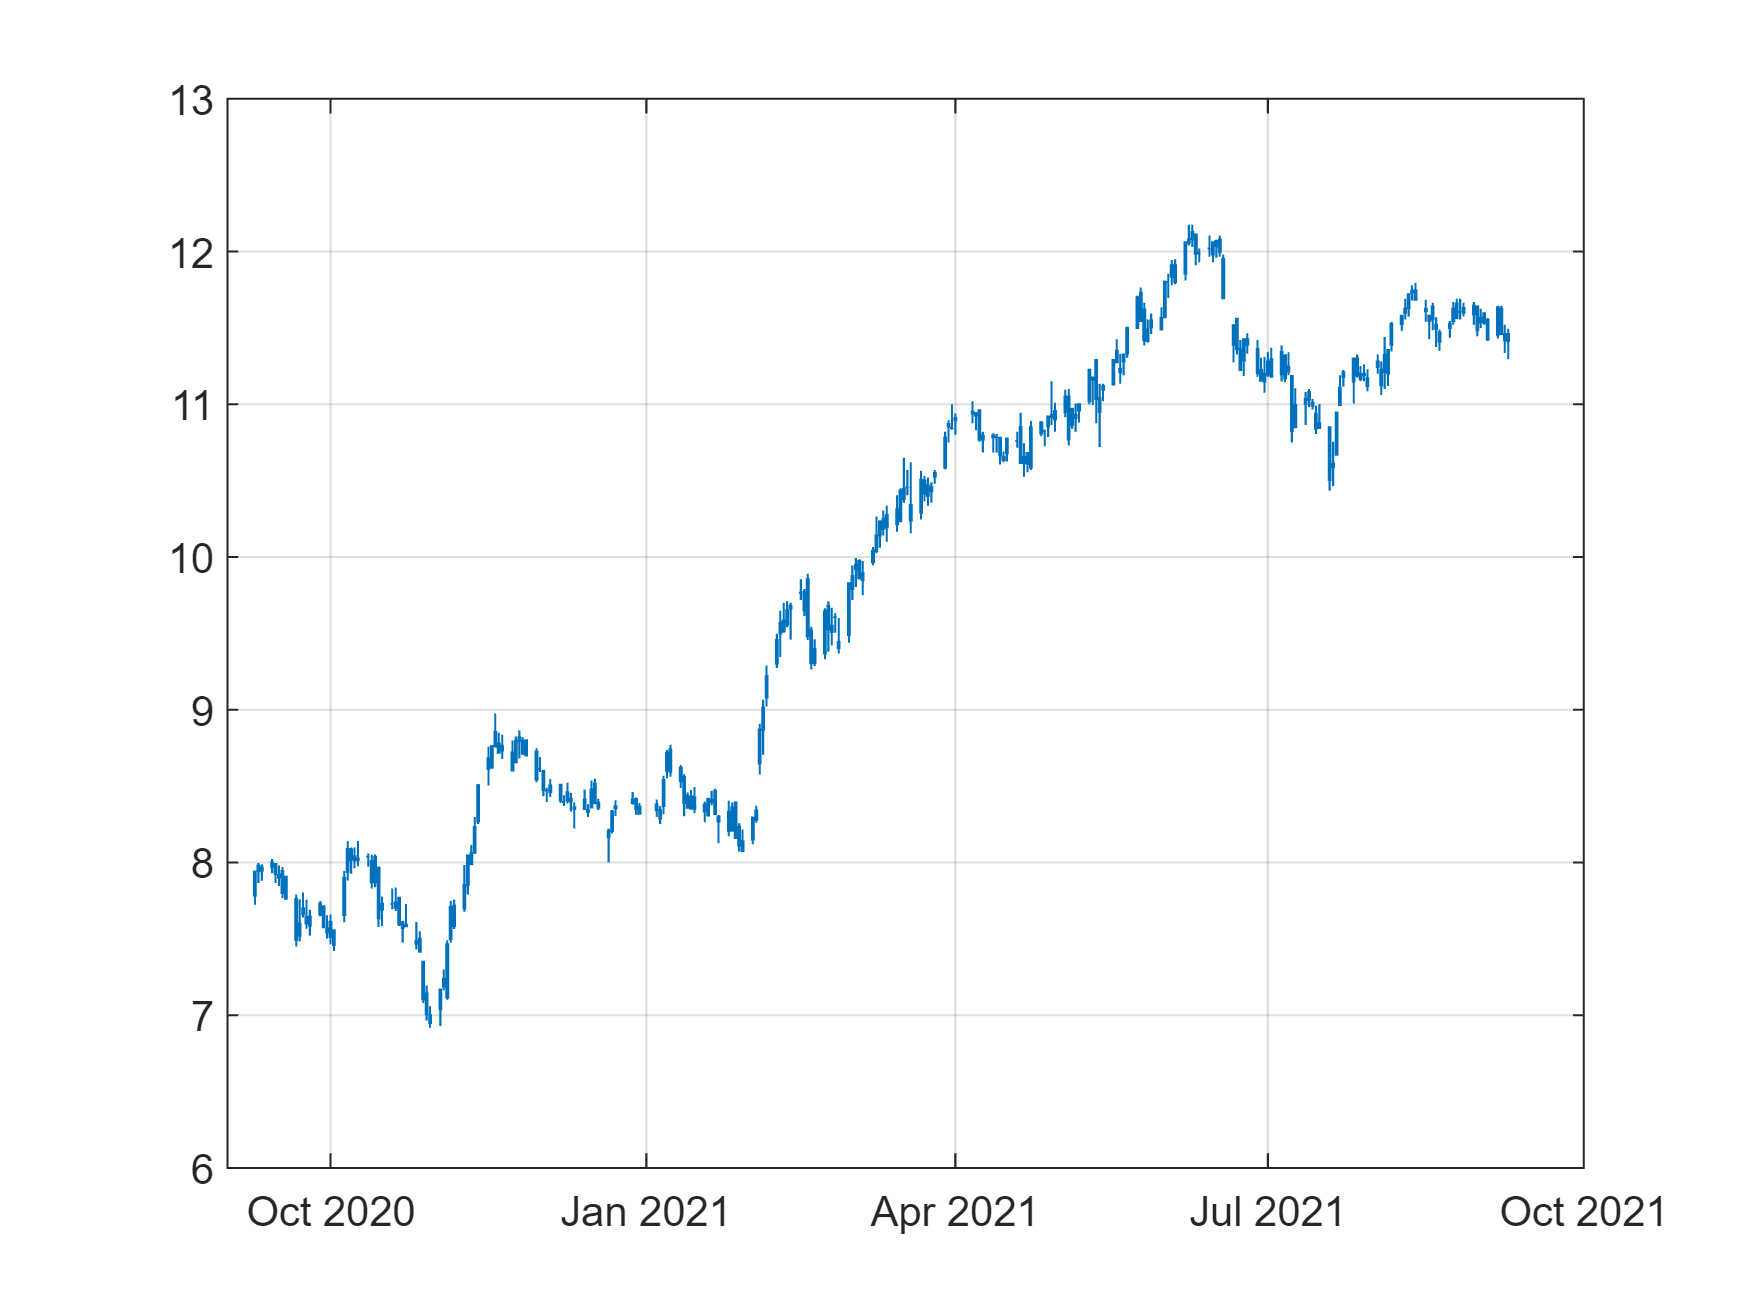

figure
candle(Y)

## I grafici che seguono si riferiscono al sottoperiodo denominato seltime

seltime=1:20;

## Grafico a candele Giapponesi delle osservazioni dentro seltime

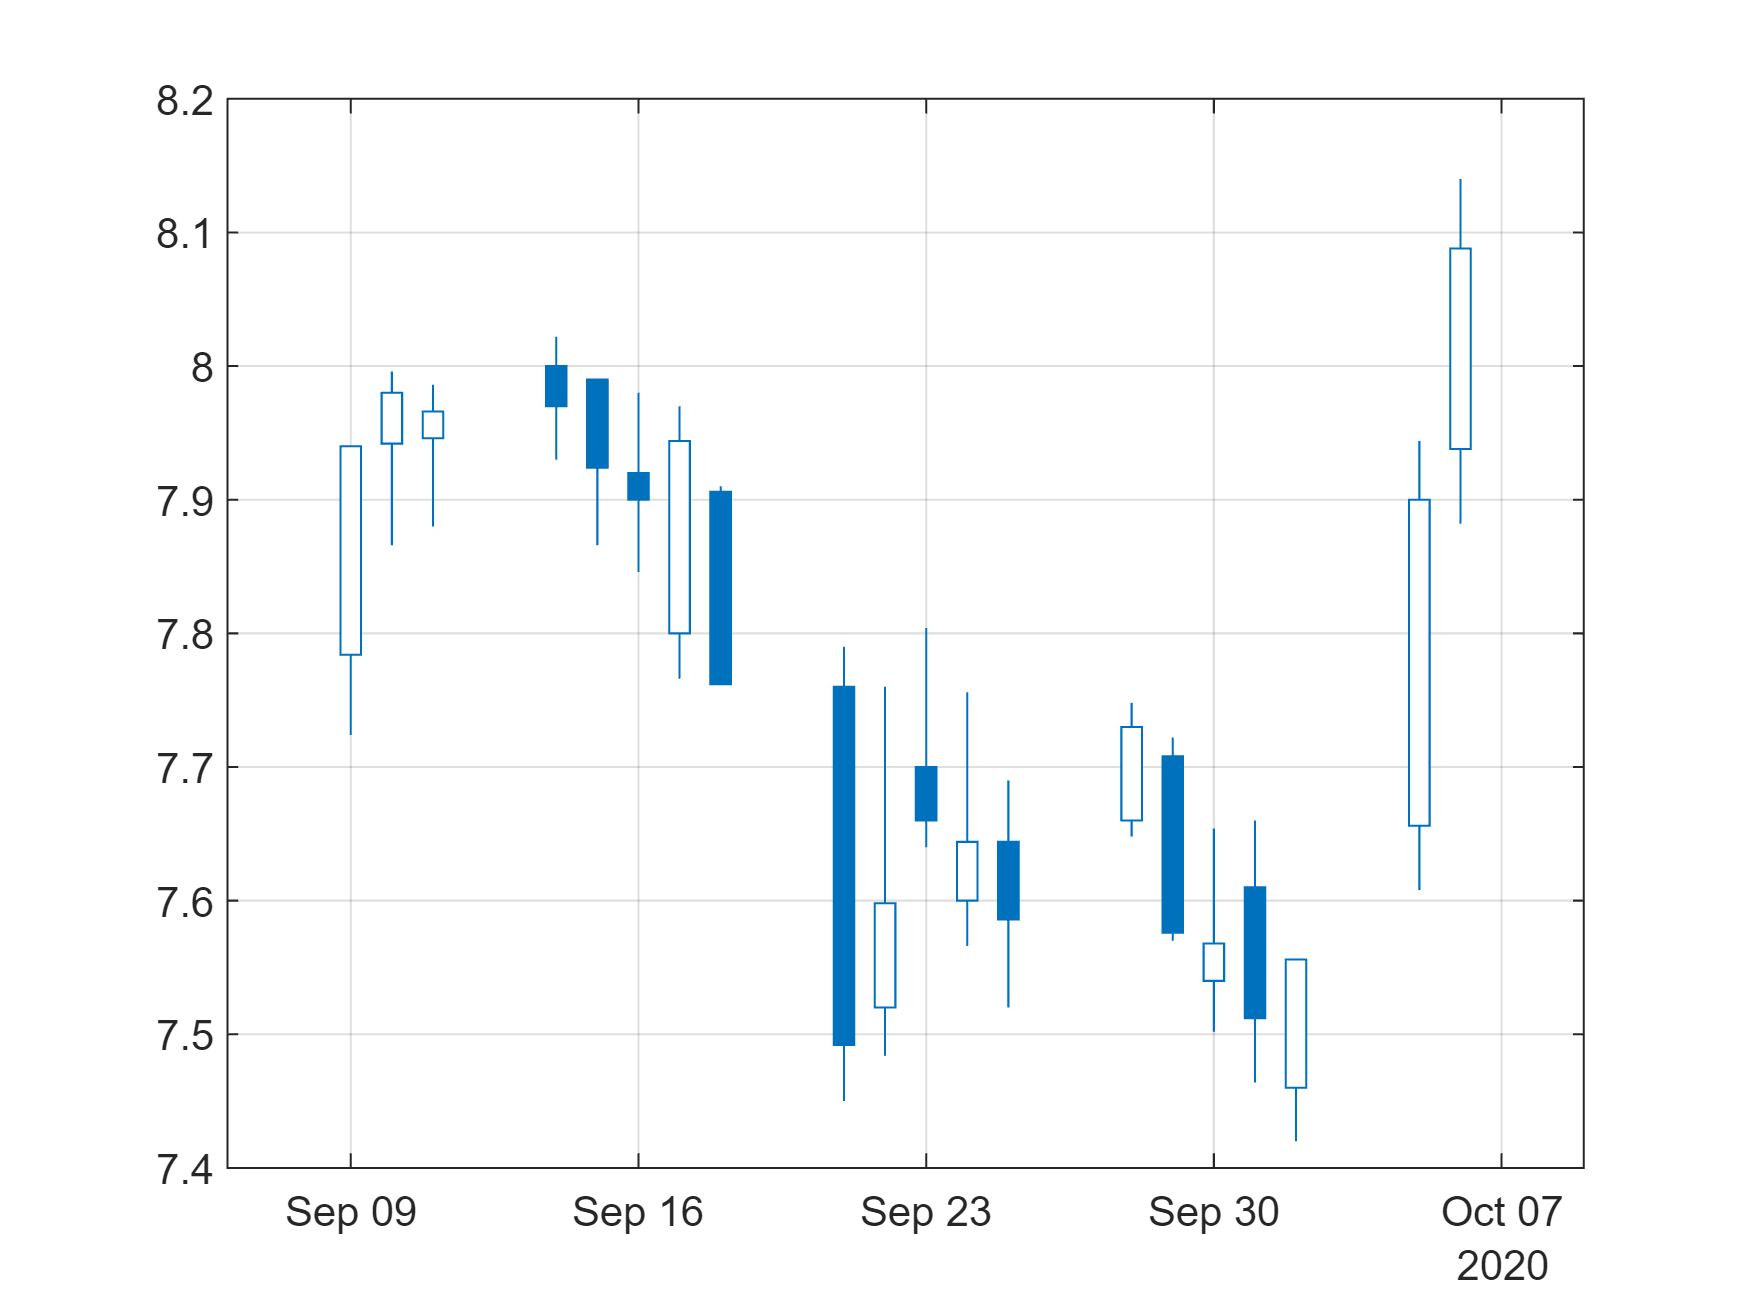

figure
candle(Y(seltime,:))

## Grafico highlow delle osservazioni dentro seltime

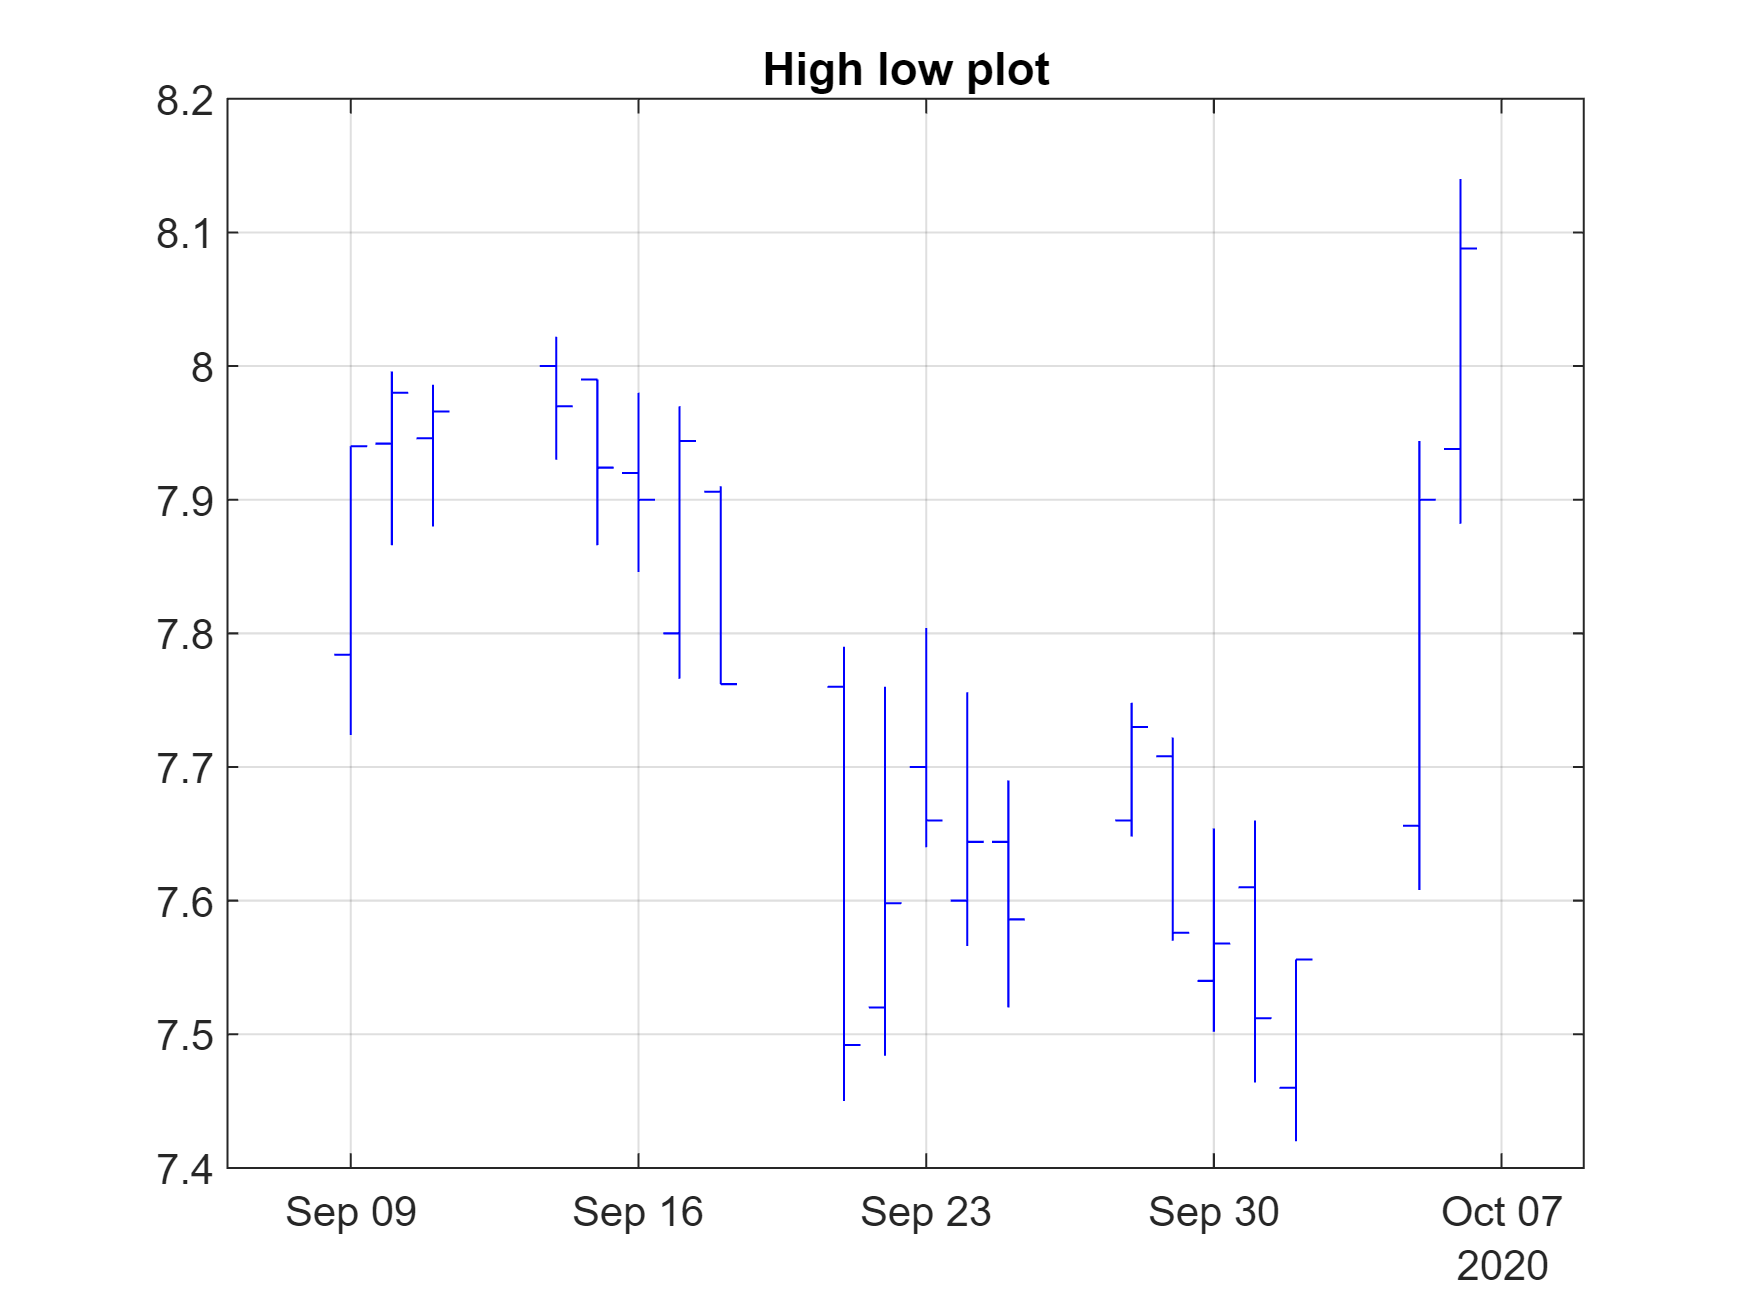

figure
highlow(Y(seltime,:),'b');
title('High low plot')

## Prezzo e volume delle osservazioni dentro seltime

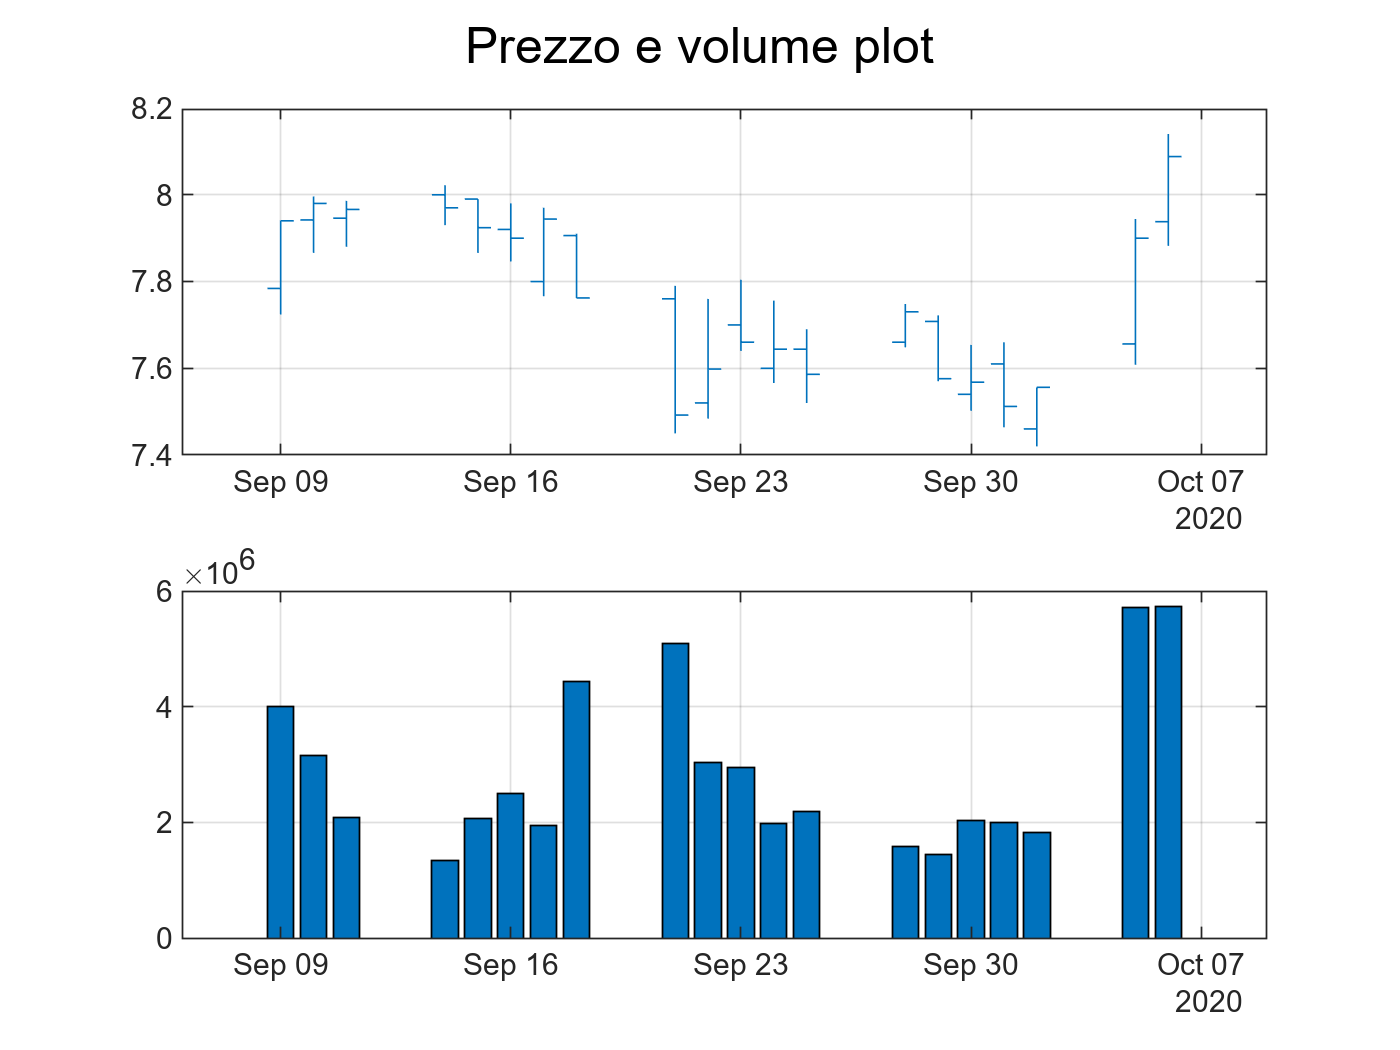

figure
Y1=Y(:,{'Open', 'High' 'Low' 'Close' 'Volume'});
priceandvol(Y1(seltime,:))
% Si noti che utilizzo l'istruzione sgtitle invece di title per inserire il
% titolo in alto e non sopra il secondo subplot.
sgtitle('Prezzo e volume plot')

La funzione kagi effettua il plot della variabile denominata Price quando l'input è una timetable. Di conseguenza andiamo a rinominare il prezzo di chiusura "Price"

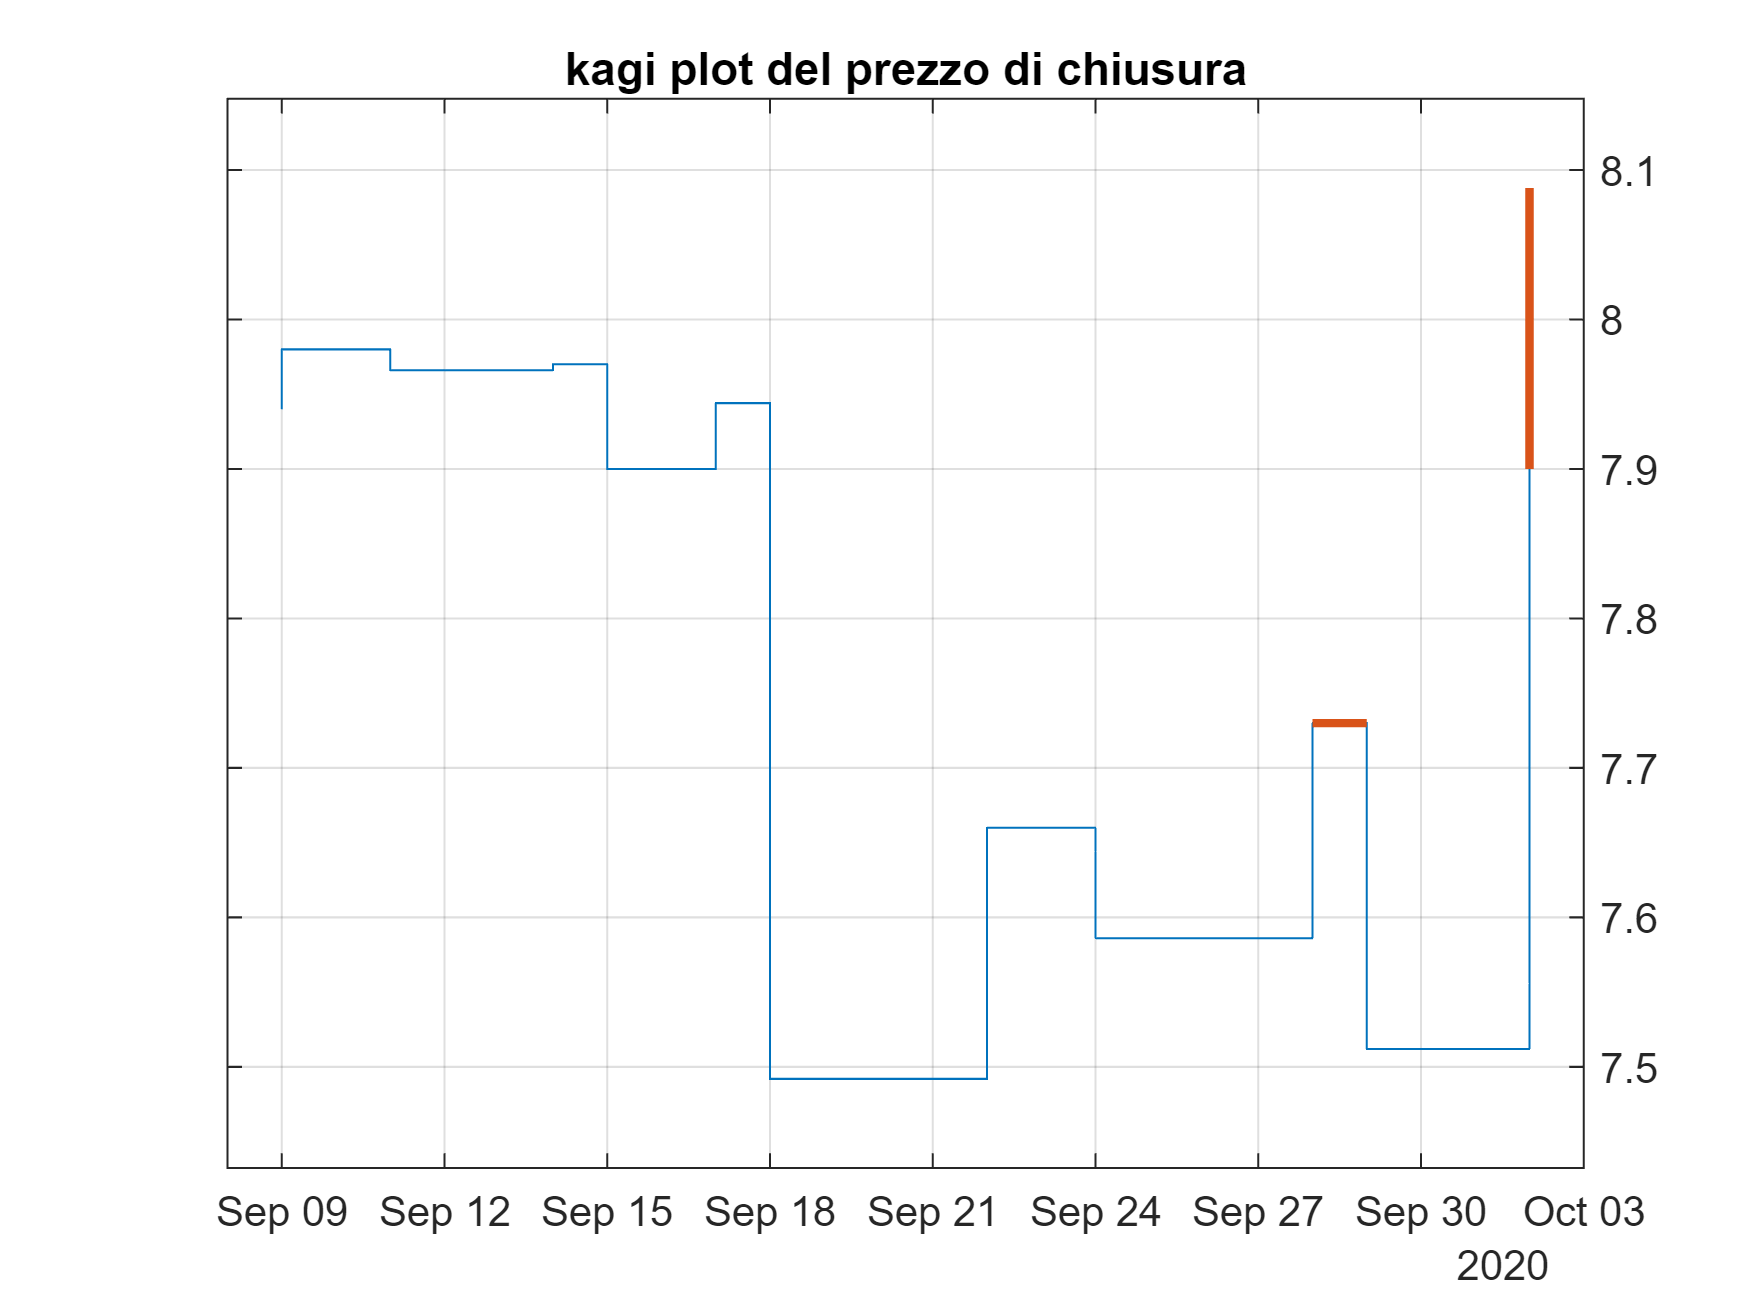

figure
Yc=Y;
Yc.Properties.VariableNames{'Close'} = 'Price';
kagi(Yc(seltime,:))
title('kagi plot del prezzo di chiusura')